# Script for Plotting Data

## Initialization

clear
close all
clc

addpath(genpath('Data'));
addpath(genpath('Figures'));
addpath(genpath('Modular Models'));
addpath(genpath('Scripts'));


lgd_font_size = 8;
fig_background_color = [0.9137, 0.9137, 0.9137];

## Sensor Calibration - Triangle Voltage Signal

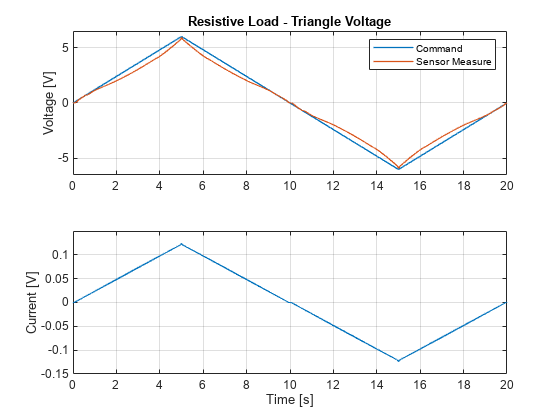

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\Resistor_Voltage_Triangle_Experiment.mat')
dataset = exp_to_std(data);
clear data

fig = figure();

subplot(2,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Sensor Measure');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([0,20]), ylim([-6.5, 6.5])
grid on

title('Resistive Load - Triangle Voltage')

subplot(2,1,2), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
xlim([0,20]), ylim([-0.15, 0.15])
grid on
exportgraphics(fig,'Figures\resistor_triangle_voltage.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear dataset

## Voltage Curve Plot

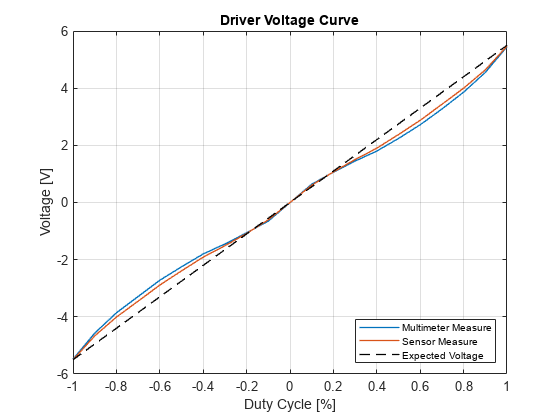

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\voltage_characteristic_verification.mat')

duty = [-flip(0.1:0.1:1), 0.1:0.1:1]';

fig = figure();
plot(duty, [voltage.resistor_multimeter, voltage.resistor_experiment], 'LineWidth', 1)
hold on, plot(duty, 5.5*duty, 'k--', 'LineWidth', 1), hold off
grid on
title('Driver Voltage Curve')
lgd = legend('Multimeter Measure', 'Sensor Measure', 'Expected Voltage', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]'), xlabel('Duty Cycle [%]')
exportgraphics(fig,'Figures\driver_voltage_characteristic.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear voltage

## Motor Staircase Velocity Plot

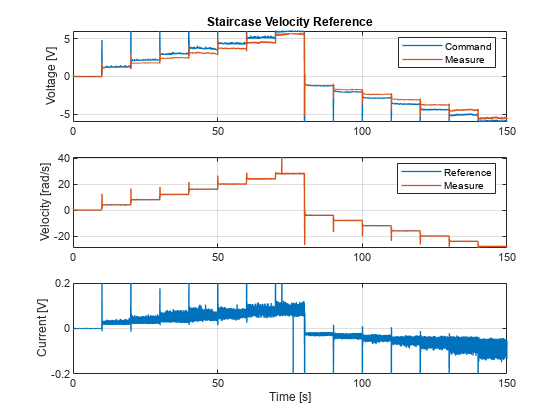

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Staircase_Experiment.mat')
dataset = exp_to_std(data);
clear data

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
dataset.reference = reshape(repmat(dataset.reference', 10000, 1), [], 1);

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
grid on

title('Staircase Velocity Reference')

subplot(3,1,2), plot(dataset.time, dataset.reference, dataset.time, dataset.velocity, 'LineWidth', 1)
lgd = legend('Reference', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
ylim([-0.2, 0.2])
grid on
exportgraphics(fig,'Figures\velocity_staircase.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear dataset

## Motor Triangle Velocity Plot

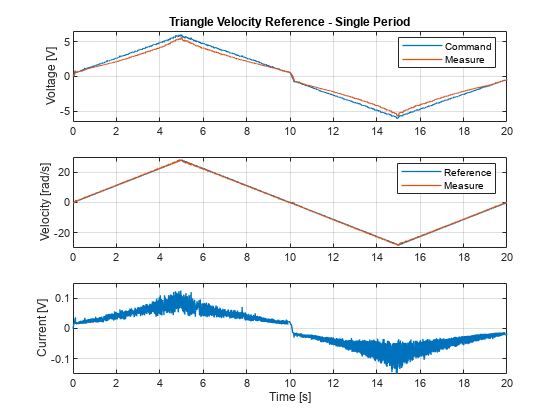

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Experiment.mat')
dataset = exp_to_std(data);
clear data

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([0,20]), ylim([-6.5, 6.5])
grid on

title('Triangle Velocity Reference - Single Period')

subplot(3,1,2), plot(dataset.time, dataset.reference, dataset.time, dataset.velocity, 'LineWidth', 1)
lgd = legend('Reference', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([0,20]), ylim([-30, 30])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
xlim([0,20]), ylim([-0.15, 0.15])
grid on
exportgraphics(fig,'Figures\velocity_triangle_period.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

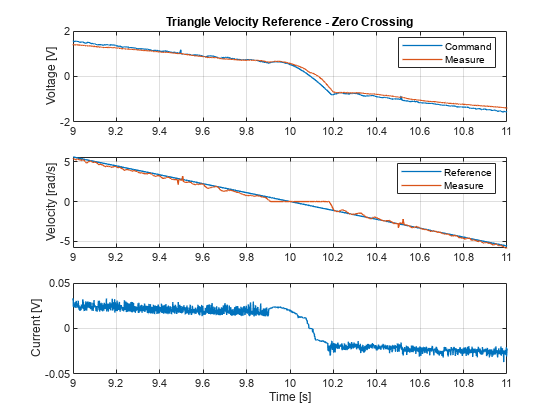

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([9,11])
grid on

title('Triangle Velocity Reference - Zero Crossing')

subplot(3,1,2), plot(dataset.time, dataset.reference, dataset.time, dataset.velocity, 'LineWidth', 1)
lgd = legend('Reference', 'Measure');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([9,11])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
xlim([9,11])
grid on
exportgraphics(fig,'Figures\velocity_triangle_zoom.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear dataset

## Flux Weakening Effect Analisys

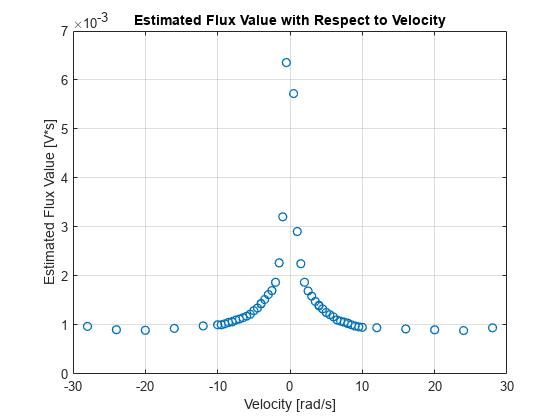

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\flux_characteristic_verification.mat')

fig = figure();

plot(kphi_curve.velocity, kphi_curve.flux, ' o', 'LineWidth', 1)
ylabel('Estimated Flux Value [V*s]'), xlabel('Velocity [rad/s]')
grid on

title('Estimated Flux Value with Respect to Velocity')
exportgraphics(fig,'Figures\flux_estimation.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

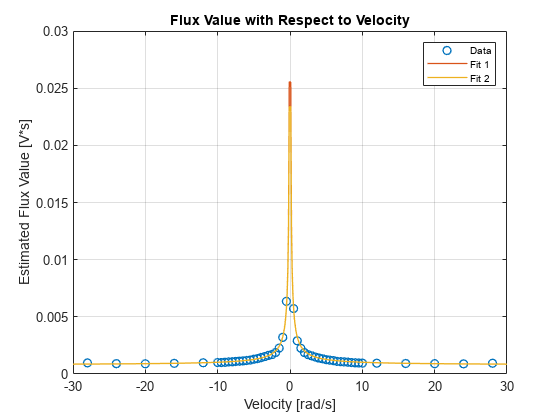

fig = figure();

plot(kphi_curve.velocity, kphi_curve.flux, ' o', kphi_curve.x_data, [kphi_curve.fit_1, kphi_curve.fit_2], 'LineWidth', 1)
ylabel('Estimated Flux Value [V*s]'), xlabel('Velocity [rad/s]')
lgd = legend('Data', 'Fit 1', 'Fit 2');
lgd.FontSize = lgd_font_size;
grid on

title('Flux Value with Respect to Velocity')
exportgraphics(fig,'Figures\flux_fitting.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear kphi_curve

## Linear Model Simulation Plot

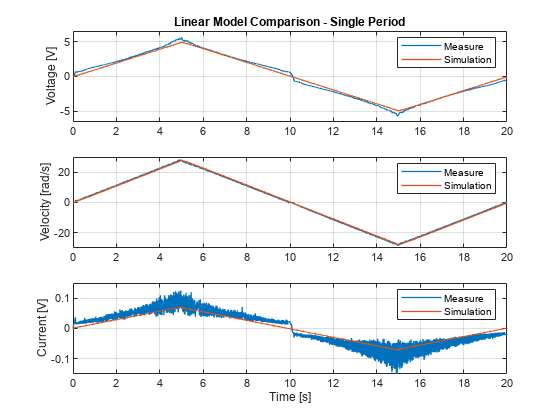

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Simulation.mat')
datasim = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Experiment.mat')
dataset = exp_to_std(data);
clear data

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
datasim.velocity = sgolayfilt(gradient(datasim.position)/1e-3, 1, 21);

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([0,20]), ylim([-6.5, 6.5])
grid on

title('Linear Model Comparison - Single Period')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([0,20]), ylim([-30, 30])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([0,20]), ylim([-0.15, 0.15])
grid on
exportgraphics(fig,'Figures\linear_comparison_period.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

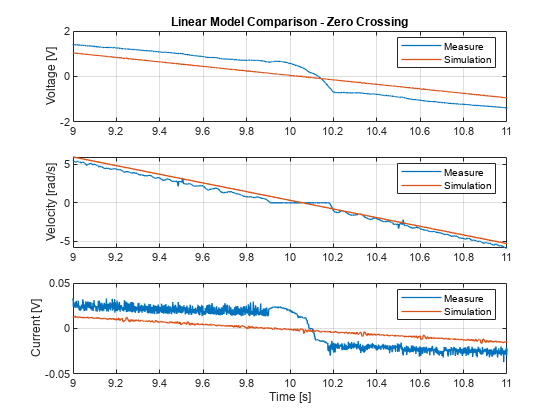

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([9,11])
grid on

title('Linear Model Comparison - Zero Crossing')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([9,11])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([9,11])
grid on
exportgraphics(fig,'Figures\linear_comparison_zoom.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear datasim, clear dataset

## Flux Weakening Simulation Plot

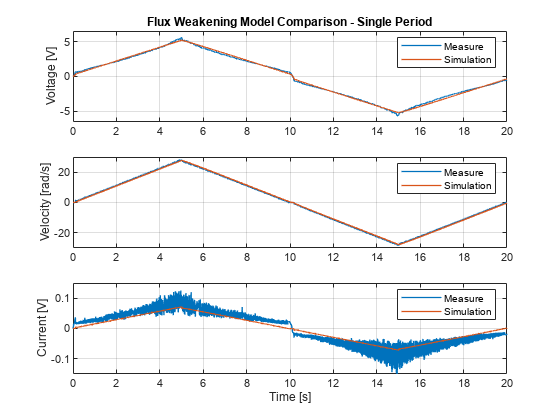

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_TriangleFW_Simulation.mat')
datasim = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Experiment.mat')
dataset = exp_to_std(data);
clear data

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
datasim.velocity = sgolayfilt(gradient(datasim.position)/1e-3, 1, 21);

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([0,20]), ylim([-6.5, 6.5])
grid on

title('Flux Weakening Model Comparison - Single Period')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([0,20]), ylim([-30, 30])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([0,20]), ylim([-0.15, 0.15])
grid on
exportgraphics(fig,'Figures\flux_comparison_period.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

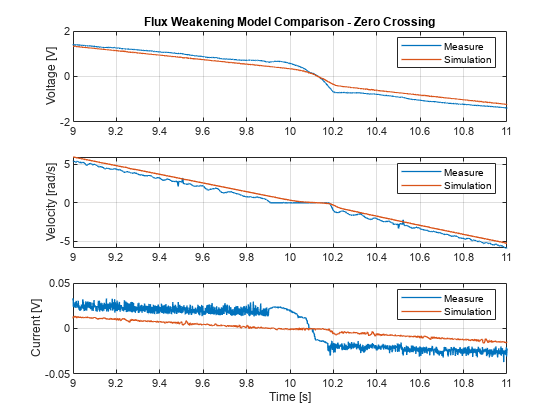

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([9,11])
grid on

title('Flux Weakening Model Comparison - Zero Crossing')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([9,11])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([9,11])
grid on
exportgraphics(fig,'Figures\flux_comparison_zoom.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear datasim, clear dataset

## Flux Weakening and Stribeck Simulation Plot

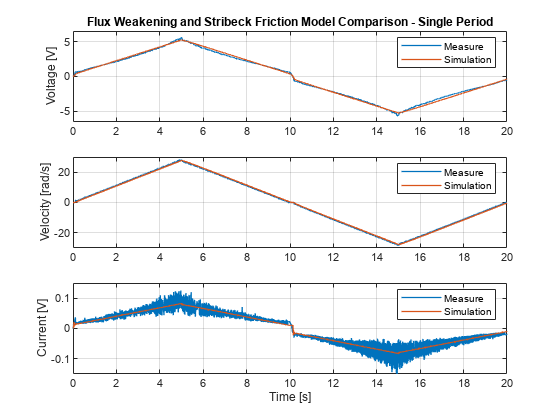

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_TriangleFW+SB_Simulation.mat')
datasim = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Experiment.mat')
dataset = exp_to_std(data);
clear data

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
datasim.velocity = sgolayfilt(gradient(datasim.position)/1e-3, 1, 21);

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([0,20]), ylim([-6.5, 6.5])
grid on

title('Flux Weakening and Stribeck Friction Model Comparison - Single Period')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([0,20]), ylim([-30, 30])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([0,20]), ylim([-0.15, 0.15])
grid on
exportgraphics(fig,'Figures\stribeck_comparison_period.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

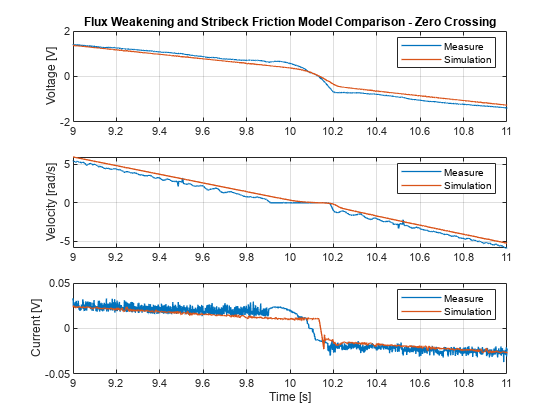

fig = figure();

subplot(3,1,1), plot(dataset.time, dataset.voltage, datasim.time, datasim.voltage, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Voltage [V]')
xlim([9,11])
grid on

title('Flux Weakening and Stribeck Friction Model Comparison - Zero Crossing')

subplot(3,1,2), plot(dataset.time, dataset.velocity, datasim.time, datasim.velocity, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Velocity [rad/s]')
xlim([9,11])
grid on

subplot(3,1,3), plot(dataset.time, dataset.current, datasim.time, datasim.current, 'LineWidth', 1)
lgd = legend('Measure', 'Simulation');
lgd.FontSize = lgd_font_size;
ylabel('Current [V]'), xlabel('Time [s]')
xlim([9,11])
grid on
exportgraphics(fig,'Figures\stribeck_comparison_zoom.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear datasim, clear dataset

## PID Position Control Plots

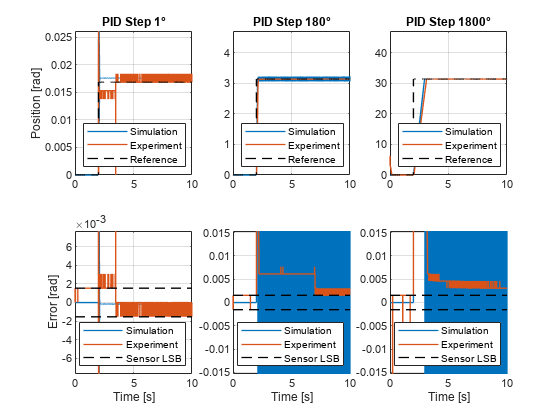

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1_Experiment.mat')
experiment.PID1 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_180_Experiment.mat')
experiment.PID180 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1800_Experiment.mat')
experiment.PID1800 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1_Simulation.mat')
simulation.PID1 = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_180_Simulation.mat')
simulation.PID180 = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1800_Simulation.mat')
simulation.PID1800 = sim_to_std(datasim);

clear data

position_LSB = 2*pi/4096;

fig = figure();

subplot(2,3,1), plot(simulation.PID1.time, simulation.PID1.position, experiment.PID1.time, experiment.PID1.position, 'LineWidth', 1)
hold on, plot(experiment.PID1.time, experiment.PID1.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylim([0, deg2rad(1.5)])
ylabel('Position [rad]')
grid on

title('PID Step 1°')

subplot(2,3,4), plot(simulation.PID1.time, simulation.PID1.reference -  simulation.PID1.position, experiment.PID1.time, experiment.PID1.reference - experiment.PID1.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]'), xlabel('Time [s]')
ylim(position_LSB*5*[-1, 1])
grid on


subplot(2,3,2),  plot(simulation.PID180.time, simulation.PID180.position, experiment.PID180.time, experiment.PID180.position, 'LineWidth', 1)
hold on, plot(experiment.PID180.time, experiment.PID180.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylim([0, deg2rad(270)])
grid on

title('PID Step 180°')

subplot(2,3,5), plot(simulation.PID180.time, simulation.PID180.reference -  simulation.PID180.position, experiment.PID180.time, experiment.PID180.reference - experiment.PID180.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
xlabel('Time [s]')
ylim(position_LSB*10*[-1, 1])
grid on


subplot(2,3,3),  plot(simulation.PID1800.time, simulation.PID1800.position, experiment.PID1800.time, experiment.PID1800.position, 'LineWidth', 1)
hold on, plot(experiment.PID1800.time, experiment.PID1800.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylim([0, deg2rad(2700)])
grid on

title('PID Step 1800°')

subplot(2,3,6), plot(simulation.PID1800.time, simulation.PID1800.reference -  simulation.PID1800.position, experiment.PID1800.time, experiment.PID1800.reference - experiment.PID1800.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
xlabel('Time [s]')
ylim(position_LSB*10*[-1, 1])
grid on
exportgraphics(fig,'Figures\PID_steps.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear datasim, clear simulation, clear experiment, clear position_LSB

## SW-PID Position Control Plots

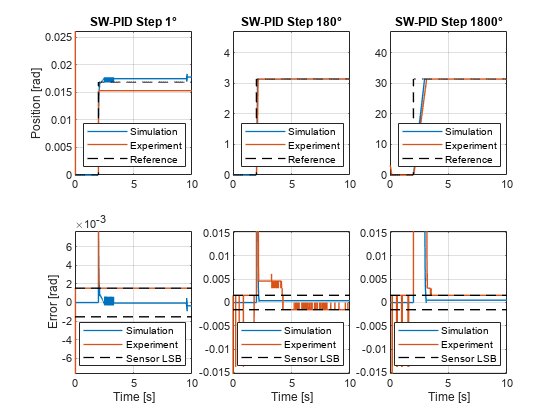

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1_Experiment.mat')
experiment.PID1 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_180_Experiment.mat')
experiment.PID180 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1800_Experiment.mat')
experiment.PID1800 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1_Simulation.mat')
simulation.PID1 = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_180_Simulation.mat')
simulation.PID180 = sim_to_std(datasim);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1800_Simulation.mat')
simulation.PID1800 = sim_to_std(datasim);

clear data

position_LSB = 2*pi/4096;

fig = figure();

subplot(2,3,1), plot(simulation.PID1.time, simulation.PID1.position, experiment.PID1.time, experiment.PID1.position, 'LineWidth', 1)
hold on, plot(experiment.PID1.time, experiment.PID1.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Position [rad]')
ylim([0, deg2rad(1.5)])
grid on

title('SW-PID Step 1°')

subplot(2,3,4), plot(simulation.PID1.time, simulation.PID1.reference -  simulation.PID1.position, experiment.PID1.time, experiment.PID1.reference - experiment.PID1.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]'), xlabel('Time [s]')
ylim(position_LSB*5*[-1, 1])
grid on


subplot(2,3,2),  plot(simulation.PID180.time, simulation.PID180.position, experiment.PID180.time, experiment.PID180.position, 'LineWidth', 1)
hold on, plot(experiment.PID180.time, experiment.PID180.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylim([0, deg2rad(270)])
grid on

title('SW-PID Step 180°')

subplot(2,3,5), plot(simulation.PID180.time, simulation.PID180.reference -  simulation.PID180.position, experiment.PID180.time, experiment.PID180.reference - experiment.PID180.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
xlabel('Time [s]')
ylim(position_LSB*10*[-1, 1])
grid on


subplot(2,3,3),  plot(simulation.PID1800.time, simulation.PID1800.position, experiment.PID1800.time, experiment.PID1800.position, 'LineWidth', 1)
hold on, plot(experiment.PID1800.time, experiment.PID1800.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylim([0, deg2rad(2700)])
grid on

title('SW-PID Step 1800°')

subplot(2,3,6), plot(simulation.PID1800.time, simulation.PID1800.reference -  simulation.PID1800.position, experiment.PID1800.time, experiment.PID1800.reference - experiment.PID1800.position, 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('Simulation', 'Experiment', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
xlabel('Time [s]')
ylim(position_LSB*10*[-1, 1])
grid on
exportgraphics(fig,'Figures\SWPID_steps.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear datasim, clear simulation, clear experiment, clear position_LSB

## Position Control Experiments Comparison Plots

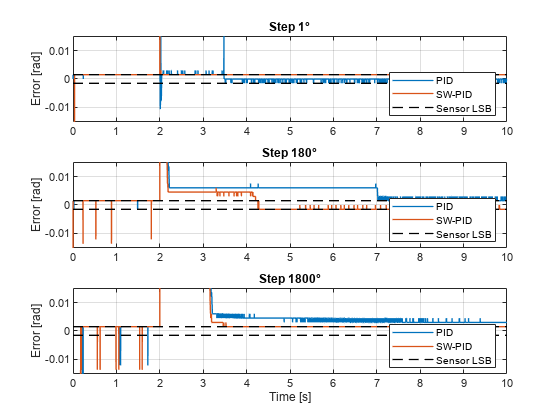

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1_Experiment.mat')
experiment.PID1 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_180_Experiment.mat')
experiment.PID180 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_1800_Experiment.mat')
experiment.PID1800 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1_Experiment.mat')
experiment.SWPID1 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_180_Experiment.mat')
experiment.SWPID180 = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_1800_Experiment.mat')
experiment.SWPID1800 = exp_to_std(data);

clear data

position_LSB = 2*pi/4096;

fig = figure();

subplot(3,1,1), plot(experiment.PID1.time, [experiment.PID1.reference, experiment.PID1.reference] - [experiment.PID1.position, experiment.SWPID1.position], 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('PID', 'SW-PID', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]')
ylim(position_LSB*10*[-1, 1])
grid on
title('Step 1°')


subplot(3,1,2), plot(experiment.PID180.time, [experiment.PID180.reference, experiment.PID180.reference] - [experiment.PID180.position, experiment.SWPID180.position], 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('PID', 'SW-PID', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]')
ylim(position_LSB*10*[-1, 1])
grid on
title('Step 180°')


subplot(3,1,3), plot(experiment.PID1800.time, [experiment.PID1800.reference, experiment.PID1800.reference] - [experiment.PID1800.position, experiment.SWPID1800.position], 'LineWidth', 1)
hold on, plot(0:10, position_LSB*[ones(11,1),-ones(11,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('PID', 'SW-PID', 'Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]'), xlabel('Time [s]')
ylim(position_LSB*10*[-1, 1])
grid on
title('Step 1800°')
exportgraphics(fig,'Figures\controller_comparison_regulation.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear experiment, clear position_LSB

## Position Tracking Plots

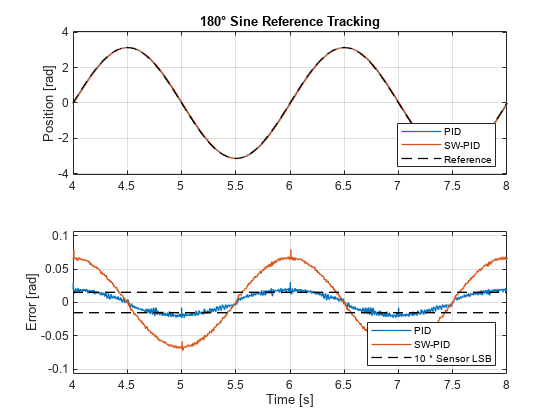

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Position_Sine_Experiment.mat')
PID = exp_to_std(data);
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\SWPID_Position_Sine_Experiment.mat')
SWPID = exp_to_std(data);

clear data

position_LSB = 2*pi/4096;

fig = figure();

subplot(2,1,1), plot(PID.time, [PID.position, SWPID.position], 'LineWidth', 1)
hold on, plot(PID.time, PID.reference, 'k--', 'LineWidth', 1), hold off
lgd = legend('PID', 'SW-PID', 'Reference', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Position [rad]')
ylim(pi*1.3*[-1, 1]), xlim([4,8])
grid on
title('180° Sine Reference Tracking')


subplot(2,1,2), plot(PID.time, [PID.reference, SWPID.reference] - [PID.position, SWPID.position], 'LineWidth', 1)
hold on, plot(0:20, 10*position_LSB*[ones(21,1),-ones(21,1)], 'k--', 'LineWidth', 1), hold off
lgd = legend('PID', 'SW-PID', '10 * Sensor LSB', 'Location', 'southeast');
lgd.FontSize = lgd_font_size;
ylabel('Error [rad]'), xlabel('Time [s]')
ylim(position_LSB*70*[-1, 1]), xlim([4,8])
grid on
exportgraphics(fig,'Figures\controller_comparison_tracking.png', 'ContentType', 'image', 'Resolution', 600, 'BackgroundColor', fig_background_color);

clear duty, clear PID, clear SWPID, clear position_LSB

## Remove remaining variables

clear